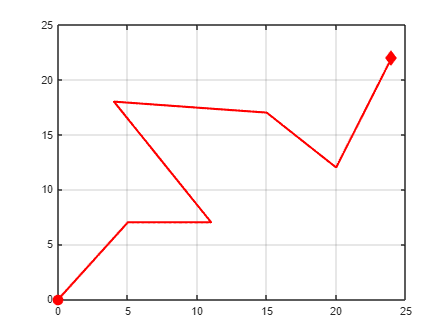

% zadanie 4.1 - sciezki
clear


P1 = [0 0];
P2 = [5 7];
P3 = [11 7];
P4 = [4 18];
P5 = [15 17];
P6 = [20 12];
P7 = [24, 22];
path_points = [P1', P2', P3', P4', P5', P6', P7'];

P12 = [linspace(P1(1), P2(1), 100); linspace(P1(2), P2(2), 100)];
P23 = [linspace(P2(1), P3(1), 100); linspace(P2(2), P3(2), 100)];
P34 = [linspace(P3(1), P4(1), 100); linspace(P3(2), P4(2), 100)];
P45 = [linspace(P4(1), P5(1), 100); linspace(P4(2), P5(2), 100)];
P56 = [linspace(P5(1), P6(1), 100); linspace(P5(2), P6(2), 100)];
P67 = [linspace(P6(1), P7(1), 100); linspace(P6(2), P7(2), 100)];

no_obstacles_path_1 = [P12, P23, P34, P45, P56, P67];

plot_path(no_obstacles_path_1)

% saveas(track, 'track.jpg') % zapisywanie figury jako obraz
init_x = no_obstacles_path_1(1,1)

init_x = 0

init_y = no_obstacles_path_1(2,1)

init_y = 0

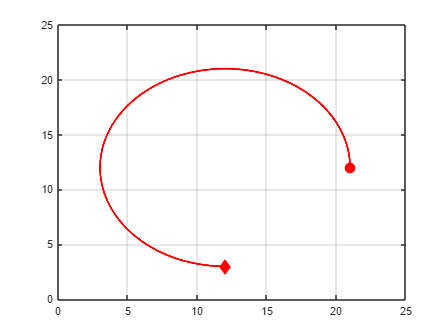

init_x = 0;
init_y = 0;
angles = linspace(0, 1.5*pi, 2000);
radius = 9;
x2Center = 12;
y2Center = 12;
x2 = radius * cos(angles) + x2Center;
y2 = radius * sin(angles) + y2Center;

no_obstacles_path_2 = [x2;y2];

plot_path(no_obstacles_path_2);

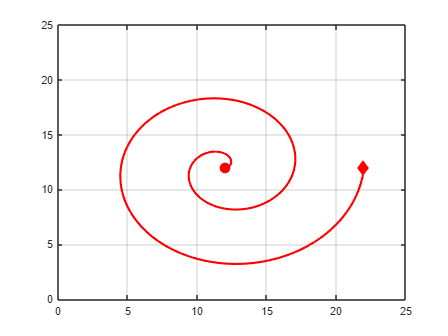

T = linspace(0, 4*pi, 300);
r = linspace(0, 10, 300); 

x = r .* cos(T) + x2Center; 

y = r .* sin(T) + y2Center;

no_obstacles_path_3 = [x; y];
plot_path(no_obstacles_path_3);

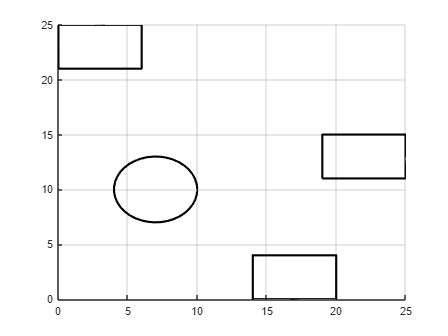

obs1 = [0, 21; 
        6, 21;
        6, 25;
        0, 25]';

angles = linspace(0, 2*pi, 40);
radius = 3;
xCenter = 7;
yCenter = 10;
x = radius * cos(angles) + xCenter;
y = radius * sin(angles) + yCenter;
obs2 = [x;y];

obs3 = [14, 0;
        20, 0;
        20, 4;
        14, 4]';

obs4 = [19, 11;
        25, 11;
        25, 15;
        19, 15]';

obstacles = {obs1, obs2, obs3, obs4};

plot_obstacles(obstacles)

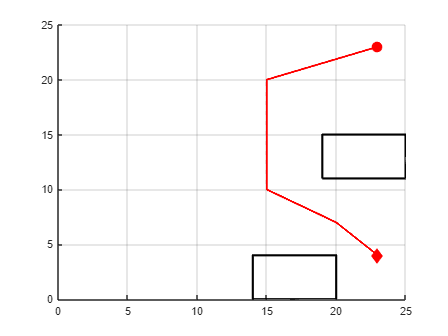

start = [23 23];
finish = [23 4];

P1 = start;
P2 = [15, 20];
P3 = [15, 10];
P4 = [20, 7];
P5 = finish;

P12 = [linspace(P1(1), P2(1), 1000); linspace(P1(2), P2(2), 1000)];
P23 = [linspace(P2(1), P3(1), 1000); linspace(P2(2), P3(2), 1000)];
P34 = [linspace(P3(1), P4(1), 1000); linspace(P3(2), P4(2), 1000)];
P45 = [linspace(P4(1), P5(1), 1000); linspace(P4(2), P5(2), 1000)];

path1_obs = [P12 P23 P34 P45];
obstacles1 = {obs4, obs3};
plot_path_obstacles(path1_obs, obstacles1)

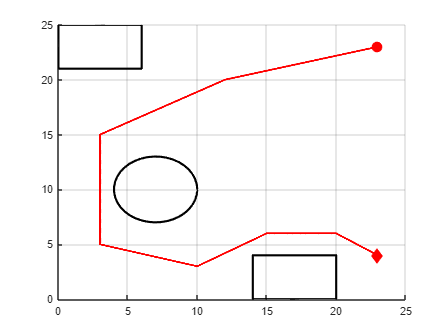

P1 = start;
P2 = [12, 20];
P3 = [3, 15];
P4 = [3, 5];
P5 = [10, 3];
P6 = [15, 6];
P7 = [20, 6];
P8 = finish;

P12 = [linspace(P1(1), P2(1), 1000); linspace(P1(2), P2(2), 1000)];
P23 = [linspace(P2(1), P3(1), 1000); linspace(P2(2), P3(2), 1000)];
P34 = [linspace(P3(1), P4(1), 1000); linspace(P3(2), P4(2), 1000)];
P45 = [linspace(P4(1), P5(1), 1000); linspace(P4(2), P5(2), 1000)];
P56 = [linspace(P5(1), P6(1), 1000); linspace(P5(2), P6(2), 1000)];
P67 = [linspace(P6(1), P7(1), 1000); linspace(P6(2), P7(2), 1000)];
P78 = [linspace(P7(1), P8(1), 1000); linspace(P7(2), P8(2), 1000)];

path2_obs = [P12 P23 P34 P45 P56 P67 P78];
obstacles2 = {obs2, obs3, obs1};
plot_path_obstacles(path2_obs, obstacles2)

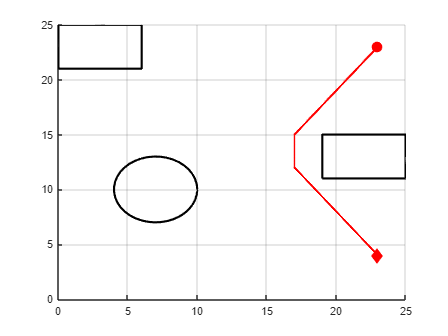

P1 = start;
P2 = [17, 15];
P3 = [17, 12];
P4 = finish;

P12 = [linspace(P1(1), P2(1), 1000); linspace(P1(2), P2(2), 1000)];
P23 = [linspace(P2(1), P3(1), 1000); linspace(P2(2), P3(2), 1000)];
P34 = [linspace(P3(1), P4(1), 1000); linspace(P3(2), P4(2), 1000)];

path3_obs = [P12 P23 P34];
obstacles3 = {obs2, obs4, obs1};
plot_path_obstacles(path3_obs, obstacles3)

% zapis do plikow
save("no_obstacles_path_1.mat", "no_obstacles_path_1");
save("no_obstacles_path_2.mat", "no_obstacles_path_2");
save("no_obstacles_path_3.mat", "no_obstacles_path_3");
save("path1_obs.mat", "path1_obs", "obstacles1");
save("path2_obs.mat", "path2_obs", "obstacles2");
save("path3_obs.mat", "path3_obs", "obstacles3");


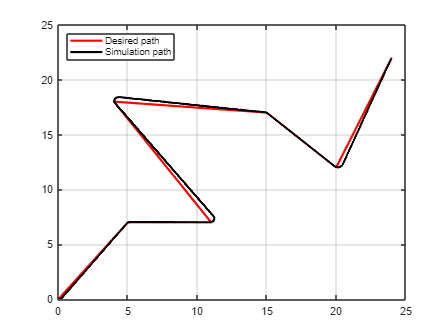

% zadanie 3
p = path_points(:, :);
[res_path, end_indices] = simulate_path(p);
plot_paths(path_points, res_path)

% zadanie 4
q = count_quality(res_path, path_points, end_indices)

q = 0.0837

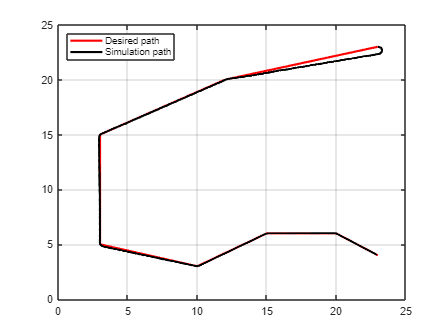

P1 = start;
P2 = [12, 20];
P3 = [3, 15];
P4 = [3, 5];
P5 = [10, 3];
P6 = [15, 6];
P7 = [20, 6];
P8 = finish;
path_points = [P1', P2', P3', P4', P5', P6', P7', P8'];
[res_path, end_indices] = simulate_path(path_points);
plot_paths(path_points, res_path)

q = count_quality(res_path, path_points, end_indices)

q = 2.9006

% zadanie 5
fun = @(x) optim(x, path_points);
lb = 0.1;
ub = 10;
x0 = 3;

x = fmincon(fun, x0, [], [], [], [], lb, ub);


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


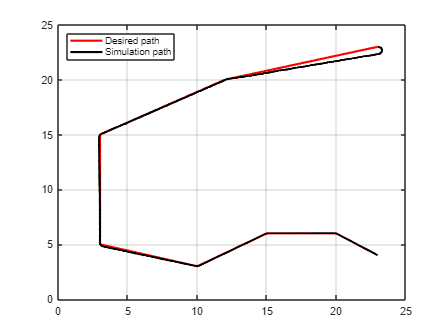

path_points = [P1', P2', P3', P4', P5', P6', P7', P8'];
[res_path, end_indices] = simulate_path(path_points);
plot_paths(path_points, res_path)

function q = optim(Kp, pathPoints)
    set_param('model/Kp', 'Value', num2str(Kp));
    [res_path, end_indices] = simulate_path(pathPoints);
    q = count_quality(res_path, pathPoints, end_indices);
end

function q = count_quality(sim_path, desired_path_points, ending_indices)
    q = 0;
    n = size(ending_indices,2);
    ending_index = 0;
    for i = 1:n
        x1 = desired_path_points(1,i);
        y1 = desired_path_points(2,i);
        x2 = desired_path_points(1,i+1);
        y2 = desired_path_points(2,i+1);
        if x1 == x2
            continue;
        else
            a = (y2 - y1) / (x2 - x1);
            b = y1 - a * x1;
        end
        starting_index = ending_index+1;
        ending_index = ending_indices(i);
        for j = starting_index:ending_index
            x_path = sim_path(1,j);
            y_path = sim_path(2,j);
            if x1 ~= x2
                y_desir = a * x_path + b;
            end
            q = q + (y_desir - y_path)^2;
        end
    end
    q = q / size(sim_path, 2);
end

set_param('model/Constant3', 'Value', '5') % ustawia Setpoint x
set_param('model/Constant4', 'Value', '5') % ustawia Setpoint y


function [res_path, ending_indices] = simulate_path(desired_path_points)
    set_param('model/Constant4', 'Value', '4') % predkosc 
    res_path = [];
    [~, n] = size(desired_path_points);
    ending_indices = [];
    % ustawienie aktualnego polozenia 
    init_x = desired_path_points(1, 1);
    init_y = desired_path_points(2, 1);
    set_param('model/Constant5', 'Value', num2str(init_x)); 
    set_param('model/Constant6', 'Value', num2str(init_y)); 
    set_param('model/Constant7', 'Value', '0'); % theta0

    for i = 2:n
        sp_x = desired_path_points(1, i);
        sp_y = desired_path_points(2, i);

        set_param('model/Constant3', 'Value', num2str(sp_x)); % ustawia Setpoint x
        set_param('model/Constant4', 'Value', num2str(sp_y)); % ustawia Setpoint y

        simOut = sim('model.slx'); % symulacja ruchu
        fi = simOut.fi(end);
        res_path = [res_path, [simOut.x1';simOut.y1']];
        ending_indices = [ending_indices, size(res_path,2)];
        % update wartosci pocztakowych
        set_param('model/Constant5', 'Value', num2str(res_path(1, end))); 
        set_param('model/Constant6', 'Value', num2str(res_path(2, end))); 
        set_param('model/Constant7', 'Value', num2str(fi));
    end
end

function lngth = count_path_length(path)
    [~, n] = size(path);
    lnght = 0;
    for i = 1:n-1
        x1 = path(1, i);
        y1 = path(2, i);
        x2 = path(1,i+1);
        y2 = path(2, i+1);
        lngth = lnght + sqrt((x1 - x2) ^ 2 + (y1 - y2) ^ 2);
    end
end

function plot_path_obstacles(path, obstacles)
    figure; hold on; grid on;
    axis([0 25 0 25]);

    % plotting obstacles
    for i = 1:length(obstacles)
        obs = obstacles{i};      
        obs = [obs, obs(:,1)];
        plot(obs(1,:), obs(2,:), 'k-', 'LineWidth', 2);
    end
    x = path(1, :);
    y = path(2, :);
    plot(x, y, 'r', 'LineWidth', 2);
    hold on;
    grid on;
    scatter(x(1), y(1), 100, 'r', 'filled'); 
    scatter(x(end), y(end), 100, 'r', 'd', 'filled'); 
    hold off;
    axis([0 25 0 25]);
end

function plot_obstacles(obstacles)
    figure; hold on; grid on;
    axis([0 25 0 25]);
    for i = 1:length(obstacles)
        obs = obstacles{i};      
        obs = [obs, obs(:,1)];
        plot(obs(1,:), obs(2,:), 'k-', 'LineWidth', 2);
    end
end

function plot_path(path)
    x = path(1, :);
    y = path(2, :);
    fig = figure;
    plot(x, y, 'r', 'LineWidth', 2);
    hold on;
    scatter(x(1), y(1), 100, 'r', 'filled'); 
    scatter(x(end), y(end), 100, 'r', 'd', 'filled'); 
    hold off;
    % axis off;
    grid on;
    axis([0, 25, 0, 25])
    % axis([-25 25 -25 25]);
end

function plot_paths(desir_path, simulation_path)
    x = desir_path(1, :);
    y = desir_path(2, :);
    fig = figure;
    plot(x, y, 'r', 'LineWidth', 2, 'DisplayName',"Desired path");
    hold on;
    % scatter(x(1), y(1), 100, 'r', 'filled'); 
    % scatter(x(end), y(end), 100, 'r', 'd', 'filled'); 

    x = simulation_path(1, :);
    y = simulation_path(2, :);

    plot(x, y, 'k', 'LineWidth', 2, 'DisplayName','Simulation path');

    % scatter(x(1), y(1), 100, 'k', 'filled'); 
    % scatter(x(end), y(end), 100, 'k', 'd', 'filled'); 
    hold off;
    % axis off;
    grid on;
    axis([0, 25, 0, 25])
    legend('Location', 'northwest');
    % axis([-25 25 -25 25]);
end